# Beamforming the PDSCH

This example generates a single layer full allocation PDSCH resource grid and applies precoding.

Specify the number of transmit antennas and set up a carrier configuration object. Here you can set up the numerology. We will use the default parameters.

nTxAntennas = 4;
carrier = nrCarrierConfig

carrier =   nrCarrierConfig with properties:

              NCellID: 1
    SubcarrierSpacing: 15
         CyclicPrefix: 'normal'
            NSizeGrid: 52
           NStartGrid: 0
                NSlot: 0
               NFrame: 0

   Read-only properties:
       SymbolsPerSlot: 14
     SlotsPerSubframe: 1
        SlotsPerFrame: 10


Set up a PDSCH configuration object. We will use 16QAM modulation and full band allocation. Other time allocation parameters and DM-RS settings can be specified in this object.

pdsch = nrPDSCHConfig;
pdsch.Modulation = "16QAM";
pdsch.PRBSet = 0:carrier.NSizeGrid-1;     % assume full band allocation

Display the PDSCH and PDSCH DM-RS parameters.

pdsch

pdsch =   nrPDSCHConfig with properties:

                NSizeBWP: []
               NStartBWP: []
             ReservedPRB: {[1×1 nrPDSCHReservedConfig]}
              ReservedRE: []
              Modulation: '16QAM'
               NumLayers: 1
             MappingType: 'A'
        SymbolAllocation: [0 14]
                  PRBSet: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51]
    VRBToPRBInterleaving: 0
           VRBBundleSize: 2
                     NID: []
                    RNTI: 1
                    DMRS: [1×1 nrPDSCHDMRSConfig]
              EnablePTRS: 0
                    PTRS: [1×1 nrPDSCHPTRSConfig]

   Read-only properties:
            NumCodewords: 1


pdsch.DMRS

ans =   nrPDSCHDMRSConfig with properties:

      DMRSConfigurationType: 1
         DMRSReferencePoint: 'CRB0'
          DMRSTypeAPosition: 2
     DMRSAdditionalPosition: 0
                 DMRSLength: 1
            CustomSymbolSet: []
                DMRSPortSet: []
                   NIDNSCID: []
                      NSCID: 0
    NumCDMGroupsWithoutData: 2

   Read-only properties:
                  CDMGroups: 0
                DeltaShifts: 0
           FrequencyWeights: [2×1 double]
                TimeWeights: [2×1 double]
    DMRSSubcarrierLocations: [6×1 double]
                 CDMLengths: [1 1]


Generate an empty resource grid. This grid represents a slot. Note the size of the generated grid. It has three dimensions: frequency (subcarrier), time (OFDM symbol) and antenna.

pdschGrid = nrResourceGrid(carrier,nTxAntennas);
size(pdschGrid)

ans =    624    14     4


Generate indices to map the PDSCH to the grid.

[pdschIndices,pdschInfo] = nrPDSCHIndices(carrier,pdsch);

Generate random PDSCH bits and map to PDSCH symbols. For simplicity, this example does not include the DL-SCH modeling. 

pdschBits = randi([0 1],pdschInfo.G,1);

Generate PDSCH symbols and apply precoding (beamforming). We assume random precoding weights;

pdschSymbols = nrPDSCH(carrier,pdsch,pdschBits);
precodingWeights = complex(randn(pdsch.NumLayers,nTxAntennas),randn(pdsch.NumLayers,nTxAntennas)); % random weights
precodingWeights = precodingWeights/(norm(precodingWeights)*sqrt(pdsch.NumLayers));                % normalize precoding weights
pdschSymbolsPrecoded = pdschSymbols*precodingWeights;

Map the PDSCH symbols to the grid and display the resource grid (first antenna). Note that the PDSCH indices are calculated for a single antenna port. After precoding, we need to map the resulting signal to multiple antennas. The function nrExtractResources() helps convert the single port PDSCH indices to multiple antennas.

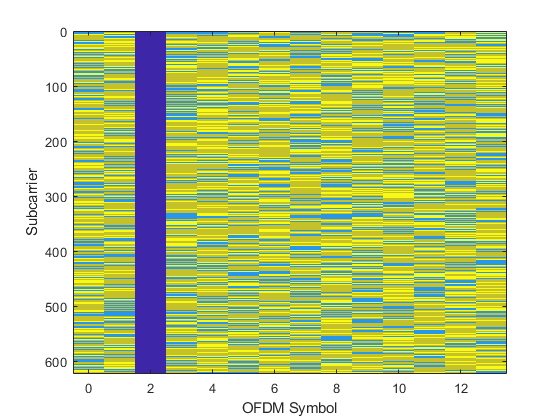

[~,pdschAntIndices] = nrExtractResources(pdschIndices,pdschGrid);
pdschGrid(pdschAntIndices) = pdschSymbolsPrecoded;
imagesc([0 carrier.SymbolsPerSlot-1],[0 carrier.NSizeGrid*12-1],abs(pdschGrid(:,:,1)));xlabel('OFDM Symbol');ylabel('Subcarrier')

Generate DM-RS symbols and indices.

dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);

Precode DM-RS symbols and map to grid. Similarly to the PDSCH, the DM-RS indices are calculated for a single port, the function nrExtractResources() is used again to convert these to multiantenna indices.

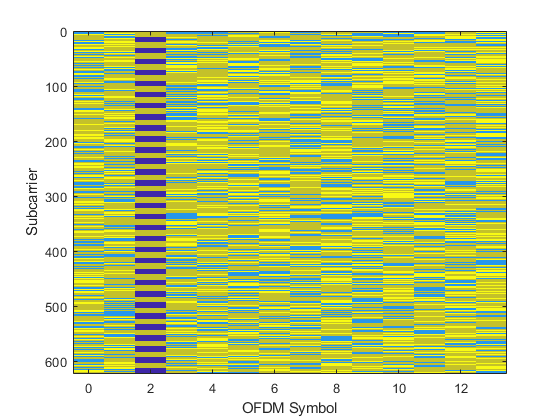

% PDSCH DM-RS precoding and mapping
for p = 1:size(dmrsSymbols,2)
    [~,dmrsAntIndices] = nrExtractResources(dmrsIndices(:,p),pdschGrid);
    pdschGrid(dmrsAntIndices) = pdschGrid(dmrsAntIndices) + dmrsSymbols(:,p)*precodingWeights(p,:);
end
%pdschGrid(dmrsIndices) = dmrsSymbols;
imagesc([0 carrier.SymbolsPerSlot-1],[0 carrier.NSizeGrid*12-1],abs(pdschGrid(:,:,1)));xlabel('OFDM Symbol');ylabel('Subcarrier')

Perform OFDM modulation of the resource grid. Display the waveform for the first antenna

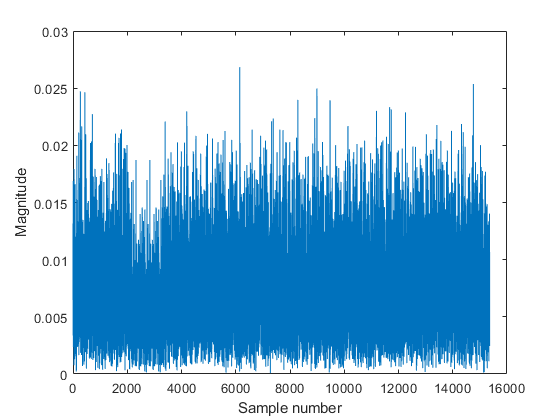

[txWaveform,waveformInfo] = nrOFDMModulate(carrier,pdschGrid);
plot(abs(txWaveform(:,1)));xlabel('Sample number');ylabel('Magnitude')